# Bar charts

Read data

load('UNdataSolarConsumption.mat');

Plot bar chart of solar power consumption in Australia

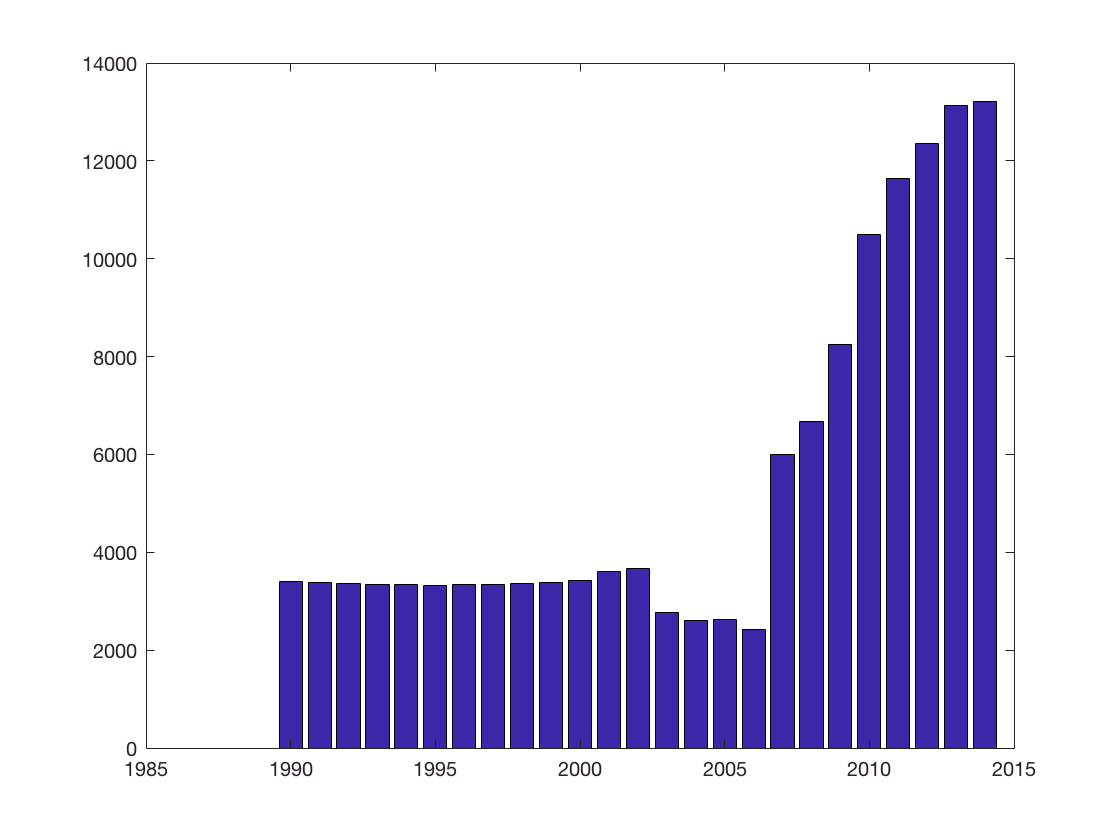

b1 = bar(year, australia_qty);

Add axis labels, and modify axis properties

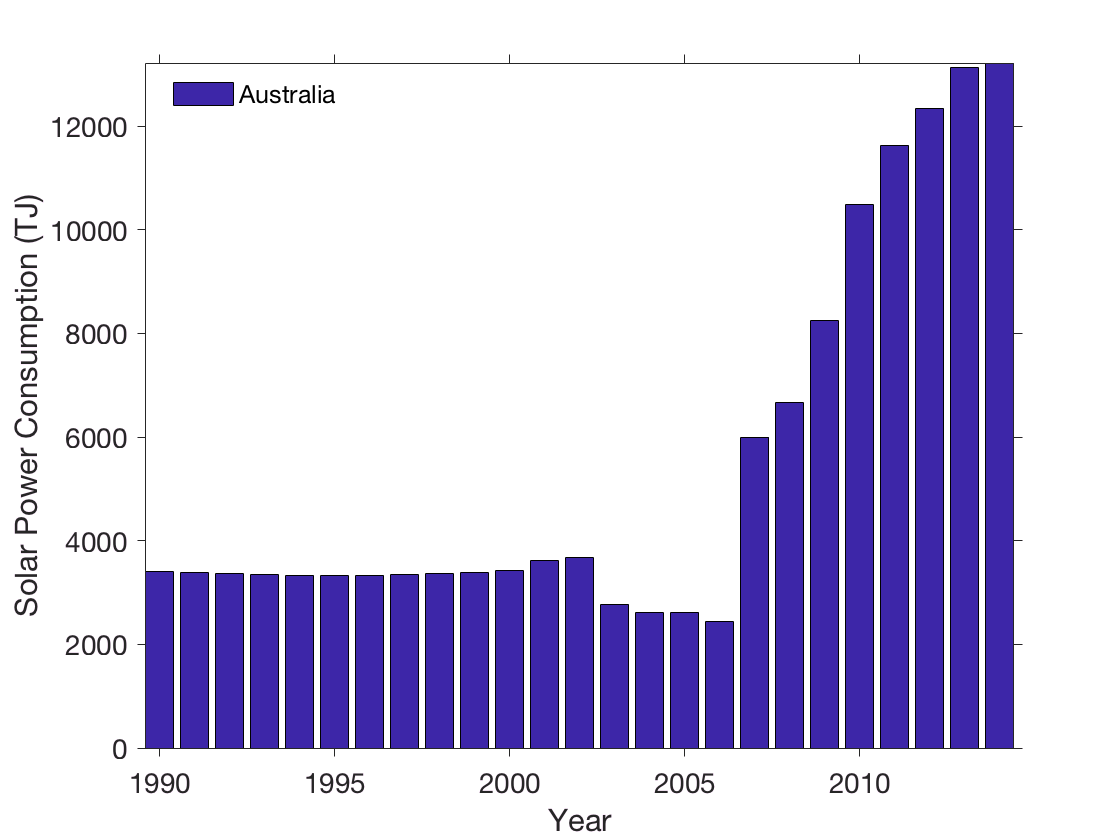

ax = gca;
ax.FontSize = 14;
ax.TickDir = 'out';
xlabel('Year', 'Fontsize', 16);
ylabel('Solar Power Consumption (TJ)', 'Fontsize', 16);
axis tight;
legend('Australia', 'Location', 'best')
legend('boxoff');

Add bars for Denmark and France data

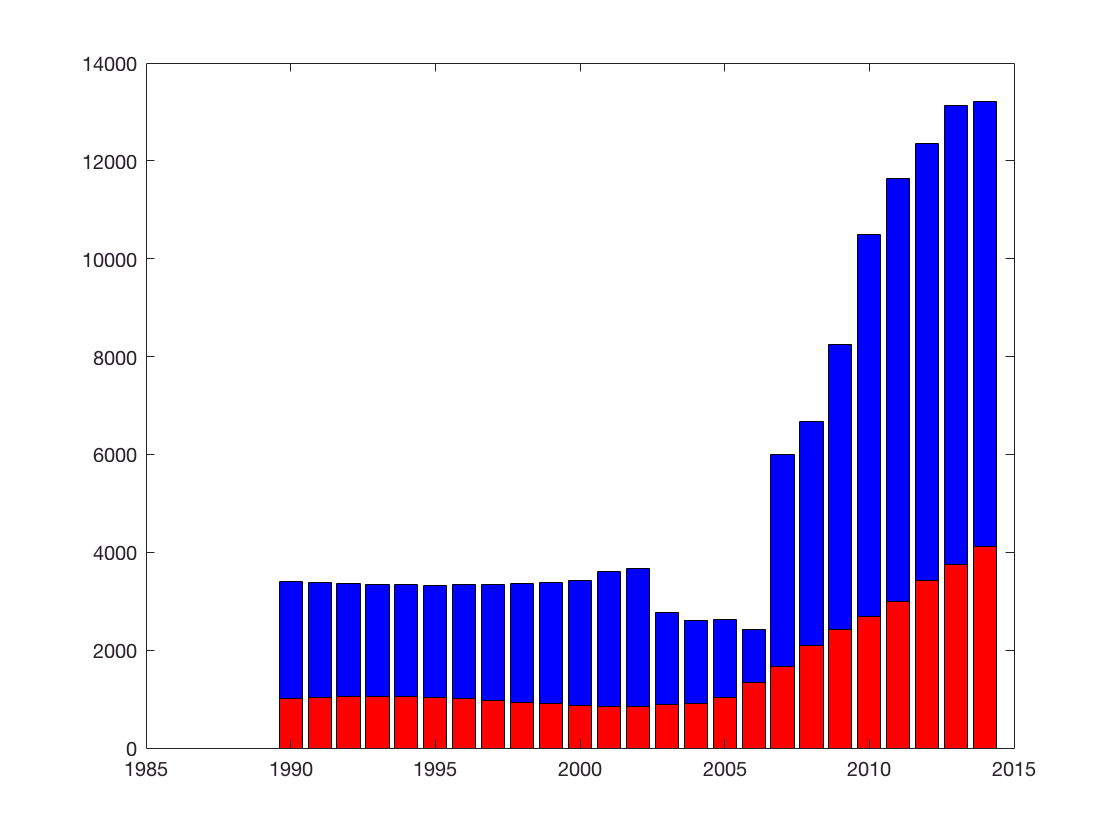

b1 = bar(year, [australia_qty france_qty], 'grouped');

Modify axis properties

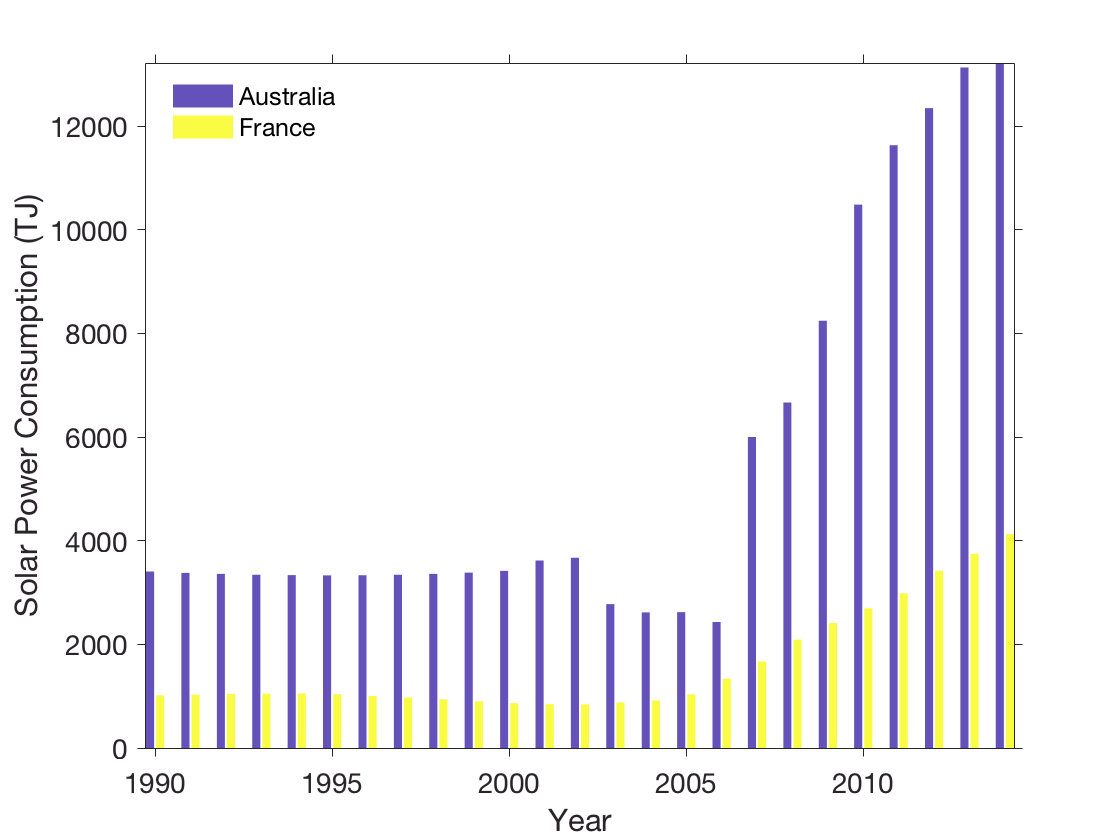

ax = gca;
ax.FontSize = 14;
ax.TickDir = 'out';
xlabel('Year', 'Fontsize', 16);
ylabel('Solar Power Consumption (TJ)', 'Fontsize', 16);
axis tight;
legend('Australia', 'France', 'Location', 'best')
legend('boxoff');
b1(1).LineStyle = 'none';
b1(2).LineStyle = 'none';
b1(1).FaceAlpha = 0.8;
b1(2).FaceAlpha = 0.8;

Add bars for data from all remaining countries

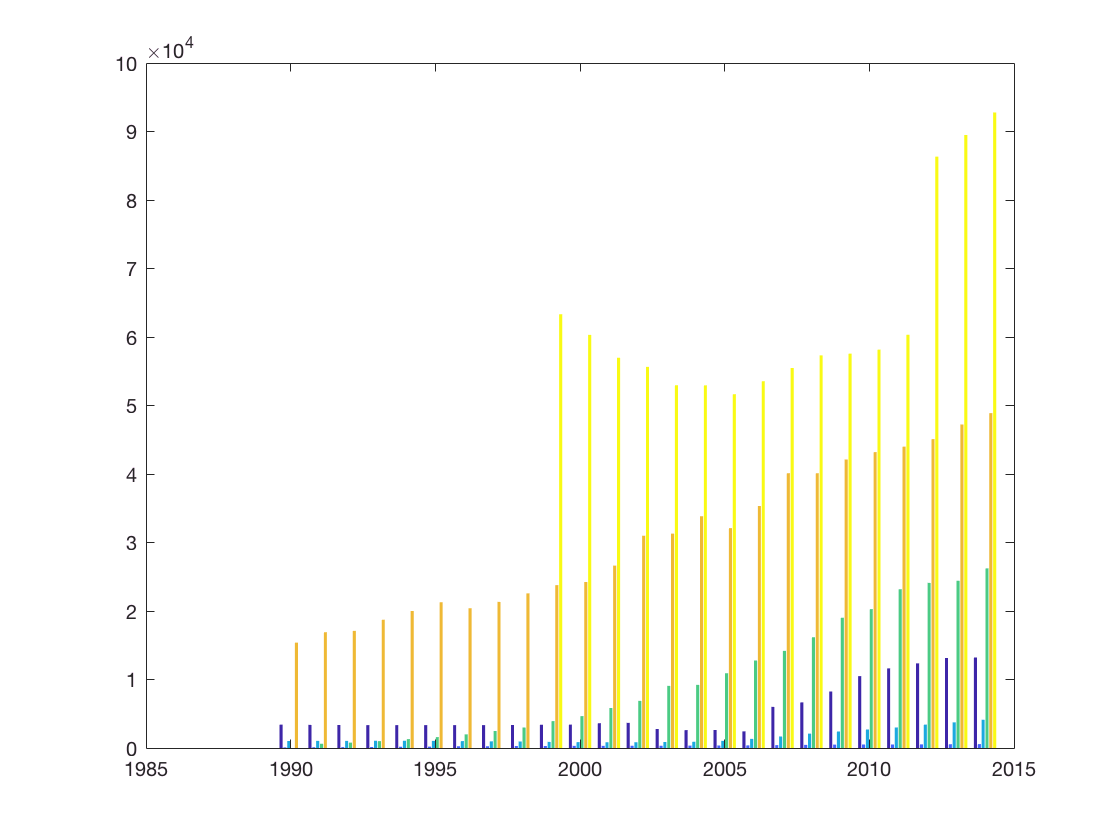

b1 = bar(year, [australia_qty denmark_qty france_qty germany_qty japan_qty usa_qty], 'grouped', 'LineStyle', 'none');

Modify axis properties

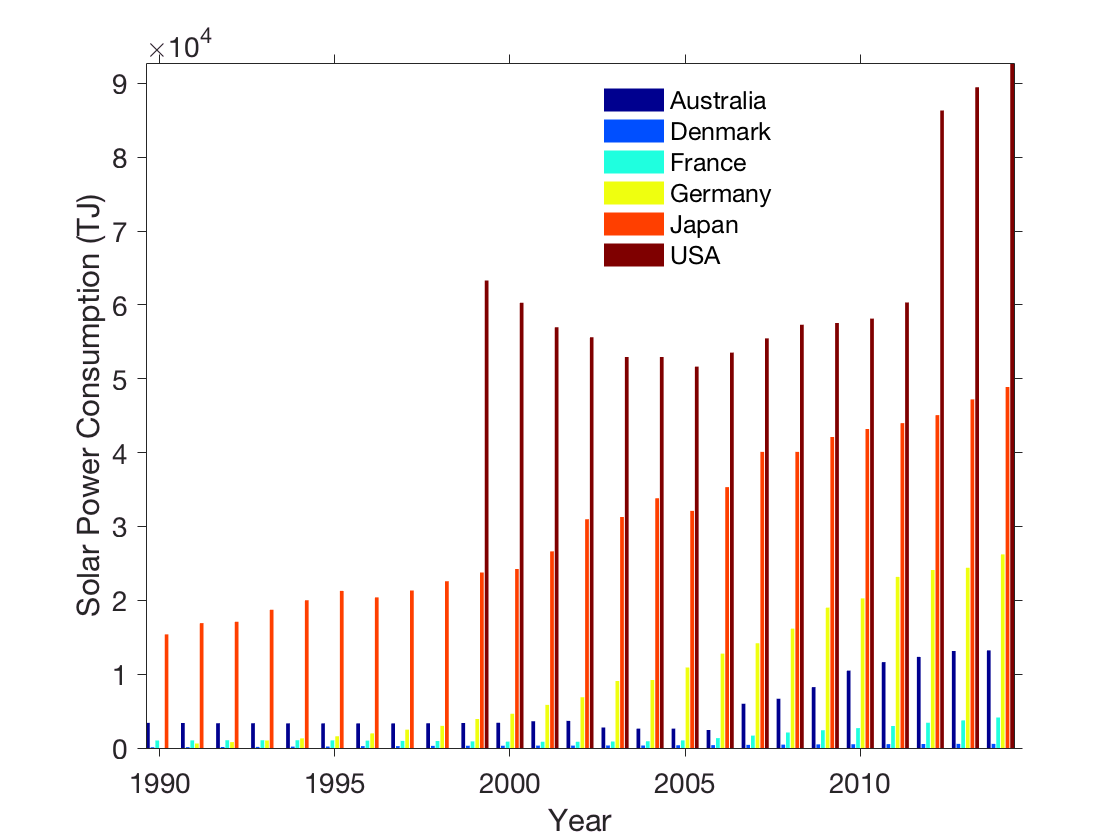

ax = gca;
ax.FontSize = 14;
ax.TickDir = 'out';
xlabel('Year', 'Fontsize', 16);
ylabel('Solar Power Consumption (TJ)', 'Fontsize', 16);
axis tight;
legend('Australia', 'Denmark', 'France', 'Germany', 'Japan', 'USA', 'Location', 'best')
legend('boxoff');
colormap('jet');

Convert to a percentage amount and plot a stacked bar chart

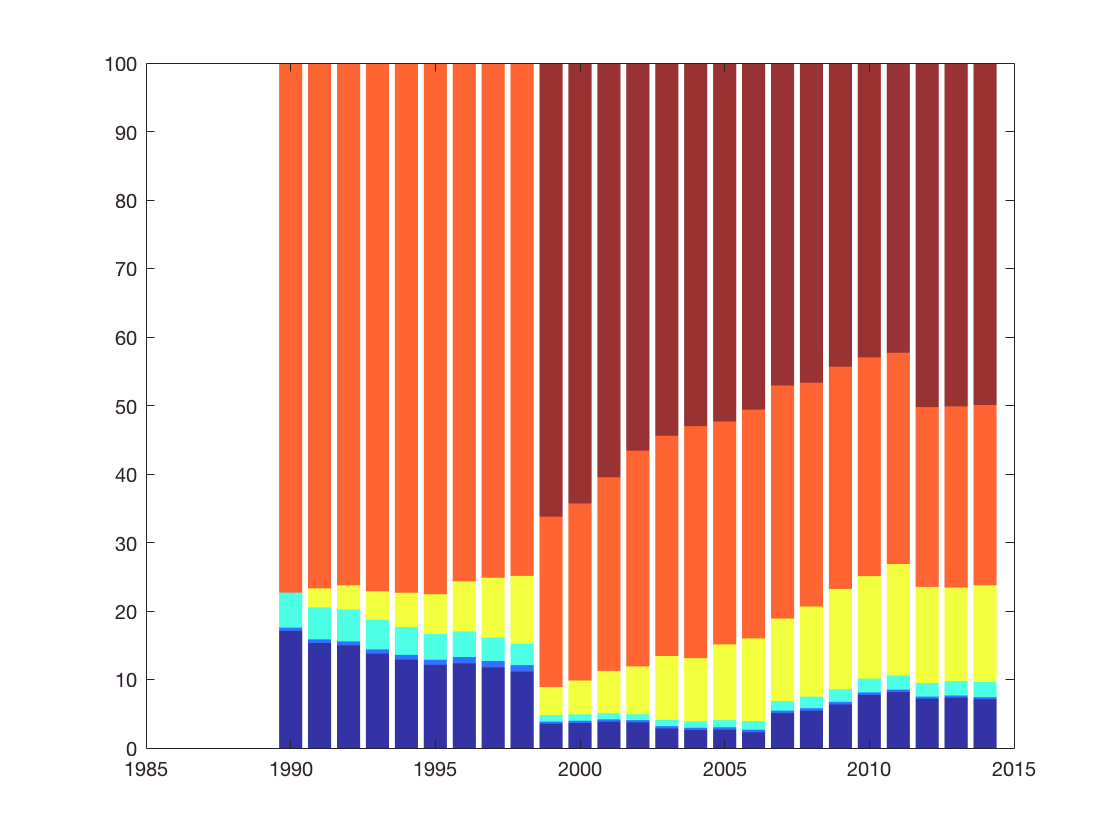

australiap = (australia_qty ./ total_qty) * 100;
denmarkp = (denmark_qty ./ total_qty) * 100;
francep = (france_qty ./ total_qty) * 100;
germanyp = (germany_qty ./ total_qty) * 100;
japanp = (japan_qty ./ total_qty) * 100;
usap = (usa_qty ./ total_qty) * 100;
b1 = bar(year, [australiap denmarkp francep germanyp japanp usap], 'stacked', 'LineStyle', 'none', 'FaceAlpha', 0.8);

Modify axis properties

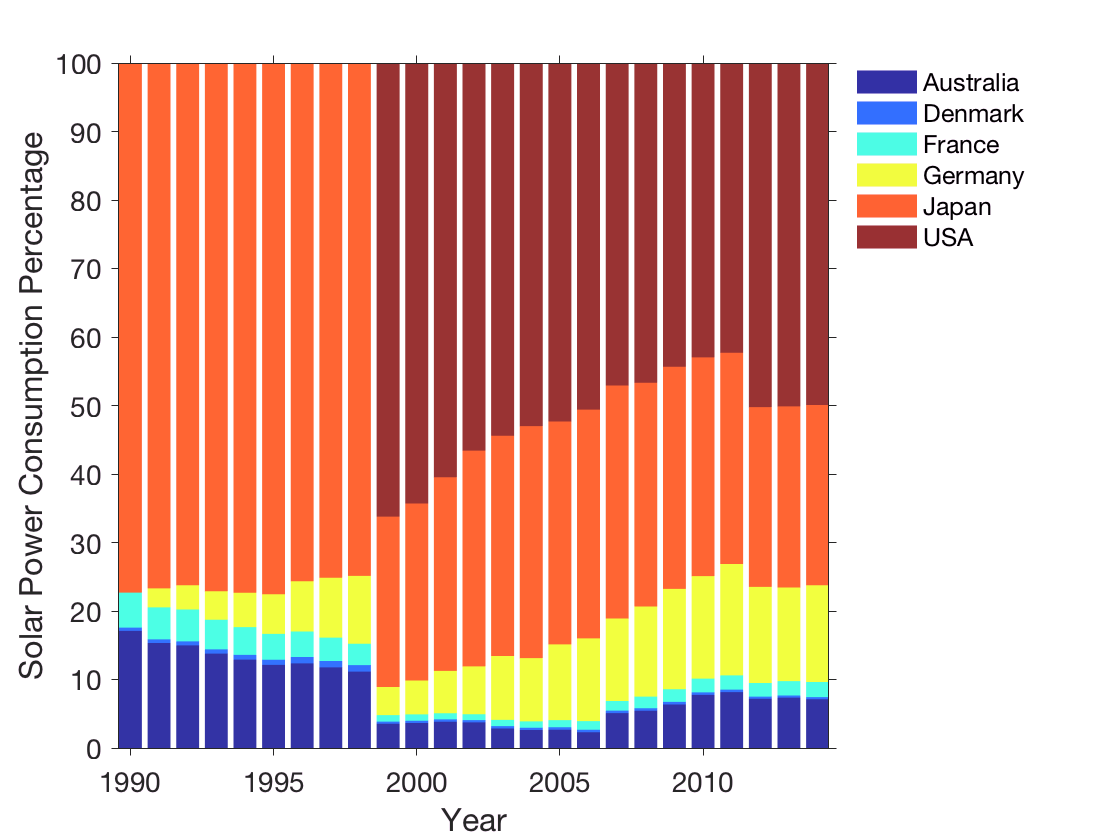

ax = gca;
ax.FontSize = 14;
ax.TickDir = 'out';
xlabel('Year', 'Fontsize', 16);
ylabel('Solar Power Consumption Percentage', 'Fontsize', 16);
axis tight;
legend('Australia', 'Denmark', 'France', 'Germany', 'Japan', 'USA', 'Location', 'bestoutside')
legend('boxoff');